# 算例说明

本算例计算的是经典的顶盖方腔流动

在压力耦合方面计算的是修正压力方程(cp)

## 清空数据

clc 
clear

## 初始化网格

global Nx Ny; %#ok<GVMIS>
Nx = 60; Ny = 60;
mesh = ConstuctMesh([Nx,Ny],[1,1]);

## 初始化松弛因子

%矩阵松弛
MAlpha_U = 0.7;
MAlpha_P = 0.3;
%物理场松弛
FAlpha_U = 0.7;
FAlpha_P = 0.3;

## 初始化循环迭代控制

simple = simple(1e4);

## 初始化物理参数

nu = 0.01;%流体粘度

## 初始化物理场

U = generatefield(mesh,fieldDimension.vol,fieldType.vector);%流体速度场
P = generatefield(mesh,fieldDimension.vol,fieldType.scalar);%流体压力场

## 物理场赋初值

U = initialFieldValue(U,[0,0,0]);
P = initialFieldValue(P,0);

## 初始化边界条件

U = setBoundaryCondition(U,[0,0,0],BCType.Dirichlet,BCSelect.w);
U = setBoundaryCondition(U,[0,0,0],BCType.Dirichlet,BCSelect.e);
U = setBoundaryCondition(U,[0,0,0],BCType.Dirichlet,BCSelect.s);
U = setBoundaryCondition(U,[1,0,0],BCType.Dirichlet,BCSelect.n);

P = setBoundaryCondition(P,0,BCType.Neumann,BCSelect.w);
P = setBoundaryCondition(P,0,BCType.Neumann,BCSelect.e);
P = setBoundaryCondition(P,0,BCType.Neumann,BCSelect.s);
P = setBoundaryCondition(P,0,BCType.Neumann,BCSelect.n);

## 初始化中间变量场

phi = generatefield(mesh,fieldDimension.face,fieldType.scalar);
phi = calculatePhi(mesh,phi,U);

## 初始化残差统计

RES = initialRes(1e4,'mass','momentum','P');
phi = calculatePhi(mesh,phi,U);

## 矩阵组装和求解

SIMPLE算法迭代开始：
SIMPLE:当前迭代步为0,

bicgstab 在解的 迭代 9 处收敛，并且相对残差为 8.6e-07。
右侧向量均为零，因此 bicgstab
返回全部为零的解，而不会进行迭代。


SIMPLE:当前迭代步为1,

bicgstab 在解的 迭代 9.5 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 10.5 处收敛，并且相对残差为 7.4e-07。


SIMPLE:当前迭代步为2,

bicgstab 在解的 迭代 10 处收敛，并且相对残差为 6.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.5e-07。


SIMPLE:当前迭代步为3,

bicgstab 在解的 迭代 10.5 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


SIMPLE:当前迭代步为4,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 5.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.2e-07。


SIMPLE:当前迭代步为5,

bicgstab 在解的 迭代 10.5 处收敛，并且相对残差为 8.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.7e-07。


SIMPLE:当前迭代步为6,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.9e-07。


SIMPLE:当前迭代步为7,

bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 5.6e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 5e-07。


SIMPLE:当前迭代步为8,

bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 6.2e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 5.2e-07。


SIMPLE:当前迭代步为9,

bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 6.1e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 5.1e-07。


SIMPLE:当前迭代步为10,

bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 5.5e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 5.3e-07。


SIMPLE:当前迭代步为11,

bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 5e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 5.3e-07。


SIMPLE:当前迭代步为12,

bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 4.7e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 5.3e-07。


SIMPLE:当前迭代步为13,

bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 4.6e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 5.3e-07。


SIMPLE:当前迭代步为14,

bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 4.5e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 5.3e-07。


SIMPLE:当前迭代步为15,

bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 4.4e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 5.2e-07。


SIMPLE:当前迭代步为16,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 9.8e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 5.2e-07。


SIMPLE:当前迭代步为17,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 9.6e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 5.1e-07。


SIMPLE:当前迭代步为18,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 9.4e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 5.1e-07。


SIMPLE:当前迭代步为19,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 9.3e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 5.1e-07。


SIMPLE:当前迭代步为20,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 9.2e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 5e-07。


SIMPLE:当前迭代步为21,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 9e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 5e-07。


SIMPLE:当前迭代步为22,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.9e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 4.9e-07。


SIMPLE:当前迭代步为23,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.9e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 4.9e-07。


SIMPLE:当前迭代步为24,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.8e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 4.9e-07。


SIMPLE:当前迭代步为25,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.9e-07。


SIMPLE:当前迭代步为26,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.9e-07。


SIMPLE:当前迭代步为27,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.8e-07。


SIMPLE:当前迭代步为28,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.5e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.7e-07。


SIMPLE:当前迭代步为29,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.5e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.6e-07。


SIMPLE:当前迭代步为30,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.4e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.6e-07。


SIMPLE:当前迭代步为31,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.4e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.5e-07。


SIMPLE:当前迭代步为32,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.4e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.5e-07。


SIMPLE:当前迭代步为33,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.3e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.4e-07。


SIMPLE:当前迭代步为34,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.3e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.3e-07。


SIMPLE:当前迭代步为35,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.3e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.3e-07。


SIMPLE:当前迭代步为36,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.2e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.2e-07。


SIMPLE:当前迭代步为37,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.2e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.2e-07。


SIMPLE:当前迭代步为38,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.2e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.1e-07。


SIMPLE:当前迭代步为39,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.2e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.1e-07。


SIMPLE:当前迭代步为40,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.1e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9e-07。


SIMPLE:当前迭代步为41,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.1e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9e-07。


SIMPLE:当前迭代步为42,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.1e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.9e-07。


SIMPLE:当前迭代步为43,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.1e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.9e-07。


SIMPLE:当前迭代步为44,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.1e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.8e-07。


SIMPLE:当前迭代步为45,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.8e-07。


SIMPLE:当前迭代步为46,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.7e-07。


SIMPLE:当前迭代步为47,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.7e-07。


SIMPLE:当前迭代步为48,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.6e-07。


SIMPLE:当前迭代步为49,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.6e-07。


SIMPLE:当前迭代步为50,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.6e-07。


SIMPLE:当前迭代步为51,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.9e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.5e-07。


SIMPLE:当前迭代步为52,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.9e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.5e-07。


SIMPLE:当前迭代步为53,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.9e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.4e-07。


SIMPLE:当前迭代步为54,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.9e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.4e-07。


SIMPLE:当前迭代步为55,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.9e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.4e-07。


SIMPLE:当前迭代步为56,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.9e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.3e-07。


SIMPLE:当前迭代步为57,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.9e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.3e-07。


SIMPLE:当前迭代步为58,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.9e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.3e-07。


SIMPLE:当前迭代步为59,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为60,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为61,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为62,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为63,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为64,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为65,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为66,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为67,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为68,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为69,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为70,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为71,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为72,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为73,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.8e-07。


SIMPLE:当前迭代步为74,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.8e-07。


SIMPLE:当前迭代步为75,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.8e-07。


SIMPLE:当前迭代步为76,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.8e-07。


SIMPLE:当前迭代步为77,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.7e-07。


SIMPLE:当前迭代步为78,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.7e-07。


SIMPLE:当前迭代步为79,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.7e-07。


SIMPLE:当前迭代步为80,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.7e-07。


SIMPLE:当前迭代步为81,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.6e-07。


SIMPLE:当前迭代步为82,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.6e-07。


SIMPLE:当前迭代步为83,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.6e-07。


SIMPLE:当前迭代步为84,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.6e-07。


SIMPLE:当前迭代步为85,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.6e-07。


SIMPLE:当前迭代步为86,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.5e-07。


SIMPLE:当前迭代步为87,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.5e-07。


SIMPLE:当前迭代步为88,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.5e-07。


SIMPLE:当前迭代步为89,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.5e-07。


SIMPLE:当前迭代步为90,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.5e-07。


SIMPLE:当前迭代步为91,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.4e-07。


SIMPLE:当前迭代步为92,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.4e-07。


SIMPLE:当前迭代步为93,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.4e-07。


SIMPLE:当前迭代步为94,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.4e-07。


SIMPLE:当前迭代步为95,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.4e-07。


SIMPLE:当前迭代步为96,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.4e-07。


SIMPLE:当前迭代步为97,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.3e-07。


SIMPLE:当前迭代步为98,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.3e-07。


SIMPLE:当前迭代步为99,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.3e-07。


SIMPLE:当前迭代步为100,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.3e-07。


SIMPLE:当前迭代步为101,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 1e-06。


SIMPLE:当前迭代步为102,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 1e-06。


SIMPLE:当前迭代步为103,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.9e-07。


SIMPLE:当前迭代步为104,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.9e-07。


SIMPLE:当前迭代步为105,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.9e-07。


SIMPLE:当前迭代步为106,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.9e-07。


SIMPLE:当前迭代步为107,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.9e-07。


SIMPLE:当前迭代步为108,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.8e-07。


SIMPLE:当前迭代步为109,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.8e-07。


SIMPLE:当前迭代步为110,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.8e-07。


SIMPLE:当前迭代步为111,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.8e-07。


SIMPLE:当前迭代步为112,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.8e-07。


SIMPLE:当前迭代步为113,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.7e-07。


SIMPLE:当前迭代步为114,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.7e-07。


SIMPLE:当前迭代步为115,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.7e-07。


SIMPLE:当前迭代步为116,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.7e-07。


SIMPLE:当前迭代步为117,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.7e-07。


SIMPLE:当前迭代步为118,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.6e-07。


SIMPLE:当前迭代步为119,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.6e-07。


SIMPLE:当前迭代步为120,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.6e-07。


SIMPLE:当前迭代步为121,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.6e-07。


SIMPLE:当前迭代步为122,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.6e-07。


SIMPLE:当前迭代步为123,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.6e-07。


SIMPLE:当前迭代步为124,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.5e-07。


SIMPLE:当前迭代步为125,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.5e-07。


SIMPLE:当前迭代步为126,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.5e-07。


SIMPLE:当前迭代步为127,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.5e-07。


SIMPLE:当前迭代步为128,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.5e-07。


SIMPLE:当前迭代步为129,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.5e-07。


SIMPLE:当前迭代步为130,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.4e-07。


SIMPLE:当前迭代步为131,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.4e-07。


SIMPLE:当前迭代步为132,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.4e-07。


SIMPLE:当前迭代步为133,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.4e-07。


SIMPLE:当前迭代步为134,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.4e-07。


SIMPLE:当前迭代步为135,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.4e-07。


SIMPLE:当前迭代步为136,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.3e-07。


SIMPLE:当前迭代步为137,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.3e-07。


SIMPLE:当前迭代步为138,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.3e-07。


SIMPLE:当前迭代步为139,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.3e-07。


SIMPLE:当前迭代步为140,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.3e-07。


SIMPLE:当前迭代步为141,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.3e-07。


SIMPLE:当前迭代步为142,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.3e-07。


SIMPLE:当前迭代步为143,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.2e-07。


SIMPLE:当前迭代步为144,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.2e-07。


SIMPLE:当前迭代步为145,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.2e-07。


SIMPLE:当前迭代步为146,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.2e-07。


SIMPLE:当前迭代步为147,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.2e-07。


SIMPLE:当前迭代步为148,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.2e-07。


SIMPLE:当前迭代步为149,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.2e-07。


SIMPLE:当前迭代步为150,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.2e-07。


SIMPLE:当前迭代步为151,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.1e-07。


SIMPLE:当前迭代步为152,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.1e-07。


SIMPLE:当前迭代步为153,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.1e-07。


SIMPLE:当前迭代步为154,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.1e-07。


SIMPLE:当前迭代步为155,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.1e-07。


SIMPLE:当前迭代步为156,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.1e-07。


SIMPLE:当前迭代步为157,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.1e-07。


SIMPLE:当前迭代步为158,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.1e-07。


SIMPLE:当前迭代步为159,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.1e-07。


SIMPLE:当前迭代步为160,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9e-07。


SIMPLE:当前迭代步为161,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9e-07。


SIMPLE:当前迭代步为162,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9e-07。


SIMPLE:当前迭代步为163,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9e-07。


SIMPLE:当前迭代步为164,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9e-07。


SIMPLE:当前迭代步为165,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9e-07。


SIMPLE:当前迭代步为166,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9e-07。


SIMPLE:当前迭代步为167,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9e-07。


SIMPLE:当前迭代步为168,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9e-07。


SIMPLE:当前迭代步为169,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.9e-07。


SIMPLE:当前迭代步为170,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.9e-07。


SIMPLE:当前迭代步为171,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.9e-07。


SIMPLE:当前迭代步为172,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.9e-07。


SIMPLE:当前迭代步为173,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.9e-07。


SIMPLE:当前迭代步为174,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.9e-07。


SIMPLE:当前迭代步为175,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.9e-07。


SIMPLE:当前迭代步为176,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.9e-07。


SIMPLE:当前迭代步为177,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.9e-07。


SIMPLE:当前迭代步为178,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.9e-07。


SIMPLE:当前迭代步为179,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.8e-07。


SIMPLE:当前迭代步为180,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.8e-07。


SIMPLE:当前迭代步为181,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.8e-07。


SIMPLE:当前迭代步为182,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.8e-07。


SIMPLE:当前迭代步为183,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.8e-07。


SIMPLE:当前迭代步为184,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.8e-07。


SIMPLE:当前迭代步为185,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.8e-07。


SIMPLE:当前迭代步为186,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.8e-07。


SIMPLE:当前迭代步为187,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.8e-07。


SIMPLE:当前迭代步为188,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.8e-07。


SIMPLE:当前迭代步为189,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.8e-07。


SIMPLE:当前迭代步为190,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.8e-07。


SIMPLE:当前迭代步为191,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.7e-07。


SIMPLE:当前迭代步为192,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.7e-07。


SIMPLE:当前迭代步为193,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.7e-07。


SIMPLE:当前迭代步为194,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.7e-07。


SIMPLE:当前迭代步为195,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.7e-07。


SIMPLE:当前迭代步为196,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.7e-07。


SIMPLE:当前迭代步为197,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.7e-07。


SIMPLE:当前迭代步为198,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.7e-07。


SIMPLE:当前迭代步为199,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.7e-07。


SIMPLE:当前迭代步为200,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.7e-07。


SIMPLE:当前迭代步为201,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.7e-07。


SIMPLE:当前迭代步为202,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.7e-07。


SIMPLE:当前迭代步为203,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.7e-07。


SIMPLE:当前迭代步为204,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.7e-07。


SIMPLE:当前迭代步为205,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.6e-07。


SIMPLE:当前迭代步为206,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.6e-07。


SIMPLE:当前迭代步为207,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.6e-07。


SIMPLE:当前迭代步为208,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.6e-07。


SIMPLE:当前迭代步为209,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.6e-07。


SIMPLE:当前迭代步为210,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.6e-07。


SIMPLE:当前迭代步为211,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.6e-07。


SIMPLE:当前迭代步为212,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.6e-07。


SIMPLE:当前迭代步为213,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.6e-07。


SIMPLE:当前迭代步为214,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.6e-07。


SIMPLE:当前迭代步为215,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.6e-07。


SIMPLE:当前迭代步为216,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.6e-07。


SIMPLE:当前迭代步为217,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.6e-07。


SIMPLE:当前迭代步为218,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.6e-07。


SIMPLE:当前迭代步为219,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.6e-07。


SIMPLE:当前迭代步为220,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


SIMPLE:当前迭代步为221,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


SIMPLE:当前迭代步为222,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


SIMPLE:当前迭代步为223,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


SIMPLE:当前迭代步为224,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


SIMPLE:当前迭代步为225,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


SIMPLE:当前迭代步为226,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


SIMPLE:当前迭代步为227,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


SIMPLE:当前迭代步为228,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


SIMPLE:当前迭代步为229,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


SIMPLE:当前迭代步为230,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


SIMPLE:当前迭代步为231,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


SIMPLE:当前迭代步为232,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


SIMPLE:当前迭代步为233,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


SIMPLE:当前迭代步为234,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


SIMPLE:当前迭代步为235,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


SIMPLE:当前迭代步为236,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


SIMPLE:当前迭代步为237,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


SIMPLE:当前迭代步为238,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


SIMPLE:当前迭代步为239,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


SIMPLE:当前迭代步为240,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


SIMPLE:当前迭代步为241,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


SIMPLE:当前迭代步为242,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


SIMPLE:当前迭代步为243,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


SIMPLE:当前迭代步为244,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


SIMPLE:当前迭代步为245,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


SIMPLE:当前迭代步为246,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


SIMPLE:当前迭代步为247,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


SIMPLE:当前迭代步为248,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


SIMPLE:当前迭代步为249,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


SIMPLE:当前迭代步为250,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


SIMPLE:当前迭代步为251,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


SIMPLE:当前迭代步为252,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


SIMPLE:当前迭代步为253,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


SIMPLE:当前迭代步为254,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


SIMPLE:当前迭代步为255,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


SIMPLE:当前迭代步为256,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


SIMPLE:当前迭代步为257,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


SIMPLE:当前迭代步为258,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


SIMPLE:当前迭代步为259,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


SIMPLE:当前迭代步为260,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


SIMPLE:当前迭代步为261,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


SIMPLE:当前迭代步为262,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


SIMPLE:当前迭代步为263,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


SIMPLE:当前迭代步为264,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


SIMPLE:当前迭代步为265,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


SIMPLE:当前迭代步为266,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


SIMPLE:当前迭代步为267,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


SIMPLE:当前迭代步为268,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


SIMPLE:当前迭代步为269,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


SIMPLE:当前迭代步为270,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


SIMPLE:当前迭代步为271,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


SIMPLE:当前迭代步为272,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


SIMPLE:当前迭代步为273,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


SIMPLE:当前迭代步为274,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


SIMPLE:当前迭代步为275,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


SIMPLE:当前迭代步为276,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


SIMPLE:当前迭代步为277,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


SIMPLE:当前迭代步为278,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


SIMPLE:当前迭代步为279,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


SIMPLE:当前迭代步为280,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


SIMPLE:当前迭代步为281,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


SIMPLE:当前迭代步为282,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


SIMPLE:当前迭代步为283,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


SIMPLE:当前迭代步为284,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


SIMPLE:当前迭代步为285,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


SIMPLE:当前迭代步为286,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


SIMPLE:当前迭代步为287,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为288,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为289,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为290,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为291,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为292,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为293,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为294,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为295,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为296,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为297,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为298,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为299,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为300,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为301,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为302,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为303,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为304,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为305,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为306,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为307,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为308,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为309,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为310,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为311,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为312,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为313,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为314,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为315,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为316,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为317,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为318,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为319,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为320,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为321,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为322,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


SIMPLE:当前迭代步为323,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为324,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为325,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为326,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为327,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为328,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为329,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为330,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为331,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为332,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为333,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为334,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为335,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为336,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为337,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为338,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为339,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为340,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为341,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为342,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为343,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为344,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为345,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为346,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为347,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为348,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为349,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为350,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为351,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为352,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为353,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为354,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为355,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为356,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为357,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为358,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为359,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为360,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为361,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为362,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为363,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为364,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为365,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为366,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为367,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为368,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为369,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为370,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为371,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为372,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为373,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为374,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为375,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为376,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


SIMPLE:当前迭代步为377,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为378,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为379,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为380,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为381,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为382,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为383,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为384,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为385,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为386,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为387,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为388,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为389,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为390,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为391,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为392,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为393,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为394,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为395,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为396,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为397,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为398,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为399,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为400,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为401,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为402,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为403,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为404,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为405,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为406,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为407,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为408,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为409,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为410,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为411,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为412,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为413,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为414,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为415,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为416,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为417,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为418,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为419,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为420,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为421,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为422,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为423,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为424,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为425,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为426,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为427,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为428,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为429,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为430,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为431,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为432,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为433,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为434,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为435,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为436,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为437,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为438,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为439,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为440,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为441,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为442,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为443,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为444,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为445,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为446,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为447,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为448,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为449,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为450,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为451,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为452,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为453,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为454,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为455,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为456,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为457,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为458,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为459,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为460,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为461,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为462,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为463,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为464,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为465,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为466,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为467,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为468,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为469,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为470,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为471,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为472,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为473,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为474,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为475,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为476,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为477,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


SIMPLE:当前迭代步为478,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为479,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为480,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为481,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为482,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为483,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为484,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为485,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为486,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为487,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为488,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为489,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为490,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为491,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为492,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为493,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为494,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为495,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为496,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为497,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为498,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为499,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为500,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为501,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为502,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为503,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为504,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为505,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为506,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为507,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为508,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为509,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为510,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为511,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为512,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为513,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为514,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为515,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为516,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为517,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为518,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为519,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为520,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为521,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为522,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为523,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为524,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为525,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为526,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为527,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为528,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为529,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为530,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为531,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为532,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为533,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为534,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为535,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为536,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为537,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为538,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为539,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为540,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为541,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为542,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为543,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为544,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为545,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为546,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为547,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为548,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为549,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为550,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为551,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为552,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为553,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为554,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为555,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为556,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为557,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为558,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为559,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为560,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为561,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为562,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为563,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为564,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为565,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为566,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为567,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为568,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为569,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为570,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为571,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为572,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为573,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为574,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为575,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为576,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为577,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为578,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为579,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为580,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为581,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为582,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为583,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为584,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为585,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为586,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为587,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为588,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为589,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


SIMPLE:当前迭代步为590,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.8e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 7.9e-07。


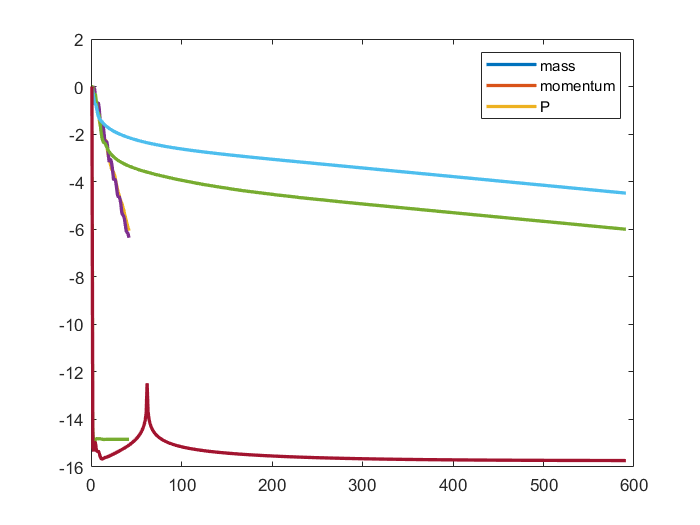

SIMPLE:当前迭代步为591,SIMPLE:Converged


%% 矩阵组装和求解
tic
while simple.loop(simple,RES,'mass',1e-6)
    %计算中间变量场
    Pgrad_F = grad_fvc(mesh,P,gradScheme.Gauss,gradType.field);
    Pgrad_Su = grad_fvc(mesh,P,gradScheme.Gauss,gradType.Su);
    %计算速度场算子
    div_U = div_fvm(mesh,phi,divScheme.upwind,U);
    lap_U = laplace_fvm(mesh,nu,laplaceScheme.Gauss,U);
    %速度场矩阵松弛求解
    [UEqn,U] = matrixSystem(U,[div_U,lap_U,Pgrad_Su],['+','-','-'],IS.solve,MAlpha_U);
    [mass,DAp,DApf,Uf] = PWIM(mesh,UEqn,U,P,RCType.ur);
    %构建修正压力(P')方程
    PEqn = laplace_fvm(mesh,DApf,laplaceScheme.Gauss,P);
    %设置参考压力
    PEqn = setPref(PEqn,3,0);
    %计算修正压力(P')
    [PEqn,P] = matrixSystem(P,[PEqn,mass],['-','-'],IS.solve);
    FAP = fullMatrix(PEqn);
    %设置参考压力
    %修正质量通量场
    phi = correctMf(mesh,phi,Uf,P,DApf);
    %修正速度(U)和压力场(P)
    [U,P] = correctUP(mesh,U,DAp,P,PEqn,PEqnType.cp,FAlpha_P); 
    %计算残差
    RES = simple.iteraRes(simple,RES,U,UEqn,'momentum');
    RES = simple.iteraRes(simple,RES,P,PEqn,'P'); 
    RES = simple.massRes(simple,RES,mass); 
    % RESULT2 = outputField(mesh,outputSelect.smooth,color.RdBu11,P);
    %绘制残差
    simple.plotRES(simple,RES); 
end

toc

历时 73.158412 秒。


## 后处理

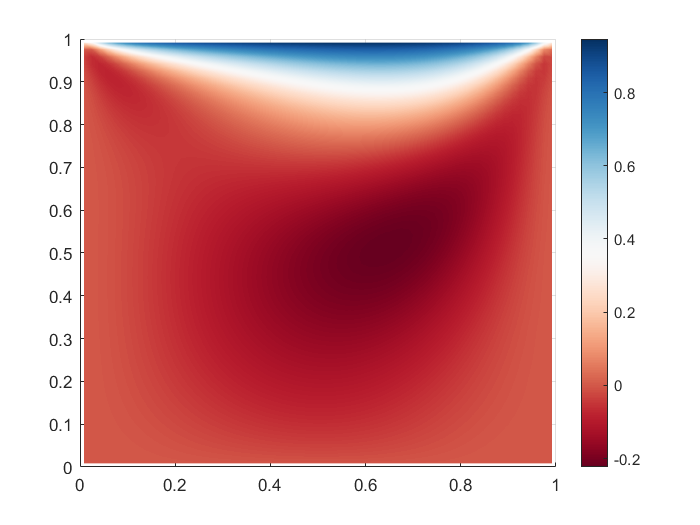

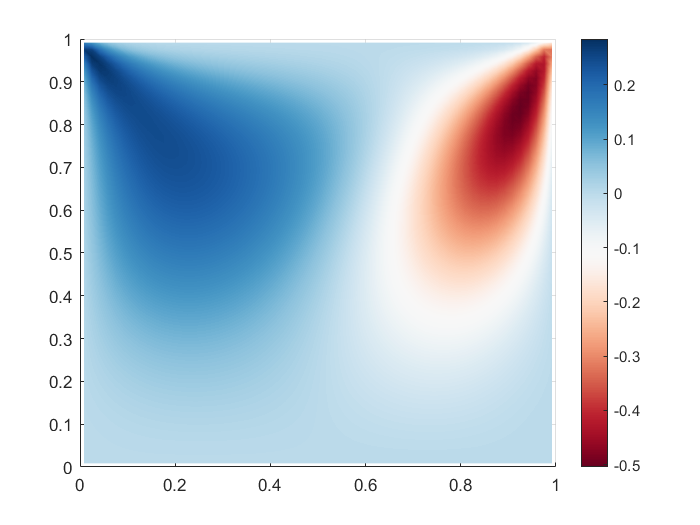

RESULT1 = outputField(mesh,outputSelect.smooth,color.RdBu11,U);

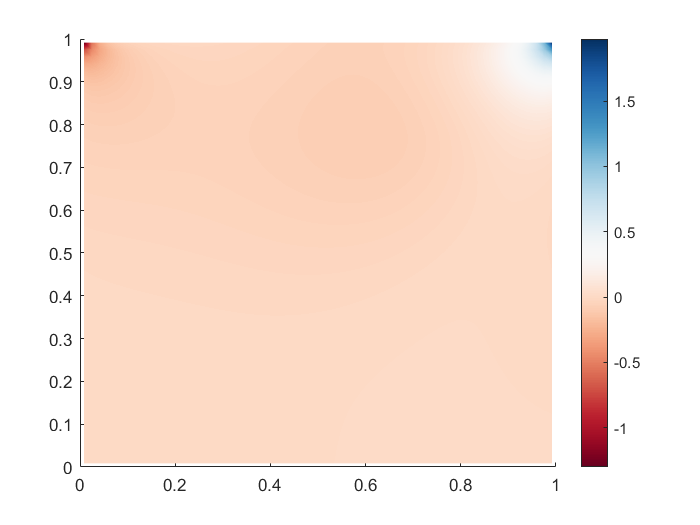

RESULT2 = outputField(mesh,outputSelect.smooth,color.RdBu11,P);

## BenchMark

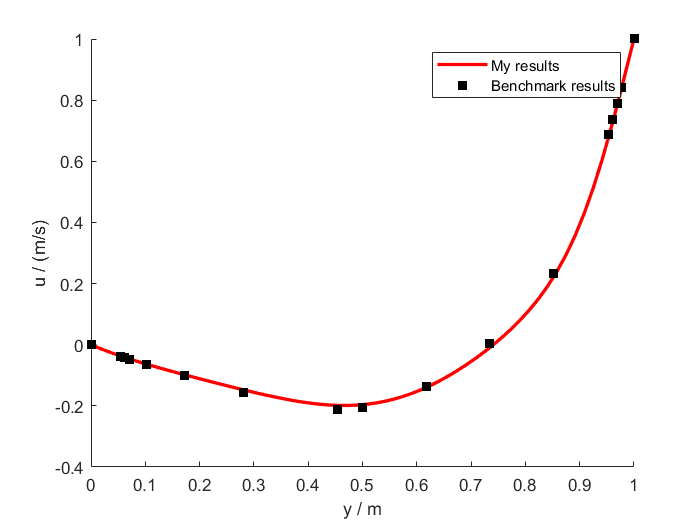

BM_cavity;